# Sample 12-6

## 画像復元

交互方向乗数法 (ADMM)

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Image restoraton

Alternating Direction Method of Multipliers (ADMM)

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

clear 
close all

### パラメータ設定

(Parameter settings)

lambda = 10^-2;
rho = 1;
niters = 100;

## 画像の読込

(Read image)

T = 0.3*im2double(imread('text.png'));
B = 0.7*imresize(checkerboard,size(T));

## 観測画像

(Observation image)

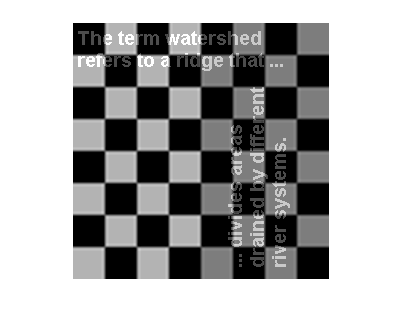

M = T + B;
figure(1)
imshow(M)

imwrite(M,'admmm.png')

### 交互方向乗数法

(Alternating direction method of multipliers)

#### 問題設定 (Problem settings):

        
$$\min_{\mathbf{u},\mathbf{y}} f(\mathbf{u})+g(\mathbf{y}),\quad  \mathbf{y}=\mathbf{Gu}$$


- $f(\cdot),g(\cdot)$: Convex functions

- $\mathbf{G}$: Full rank matrix

#### アルゴリズム (Algorithm):

- Initialization: $\mathbf{d}^{(0)}$,$\mathbf{y}^{(0)}$, $t\leftarrow 0$

- 
$$\mathbf{u}^{(t+1)} \leftarrow \arg \min _{\mathbf{x}} f(\mathbf{x})+\frac{\rho}{2}\left\|\mathbf{y}^{(t)}-\mathbf{G} \mathbf{x}-\mathbf{d}^{(t)}\right\|_{2}^{2}$$


- 
$$\mathbf{y}^{(t+1)} \leftarrow \mathrm{prox}_{\rho^{-1} g}\left(\mathbf{G} \mathbf{u}^{(t+1)}+\mathbf{d}^{(t)}\right)$$


- 
$$\mathbf{d}^{(t+1)} \leftarrow \mathbf{d}^{(t)}+\mathbf{G} \mathbf{u}^{(t+1)}-\mathbf{y}^{(t+1)}$$


- If a stopping critera is satisfied then finish, otherwise $t\rightarrow t+1$ and go to Step 2.

ただし，(where) 

        
$$\rho>0$$


【Example】Robust principal component analysis (Robust PCA)

        
$$\mathbf{M}=\mathbf{L}+\mathbf{S}$$


問題設定(Problem settings)

        
$$\min _{\mathbf{L}, \mathbf{S}}\|\mathbf{L}\|_{*}+\lambda\|\mathbf{S}\|_{1},\ \quad \mathrm{s.t.}\ \mathbf{M}=\mathbf{L}+\mathbf{S}$$


            
$$\Updownarrow$$


        
$$\min_{\mathbf{u},\mathbf{y}} f(\mathbf{u})+g(\mathbf{y}),\quad  \mathbf{y}=\mathbf{Gu}$$


ただし，(where)

- $\|\cdot\|_{*}$: Nuclear norm (sum of singular values $\{\sigma_k\}$)

- $\|\cdot\|_{1}$: $\ell_1$-norm as a vector (sum of absolute of elements)

imgZ1 = M;
imgZ2 = zeros(size(M),'like',M);
imgZ3 = M;
imgD1 = zeros(size(M),'like',M);
imgD2 = zeros(size(M),'like',M);
imgD3 = zeros(size(M),'like',M);

for idx=1:niters   
    % State variables
    Z1 = imgZ1;
    Z2 = imgZ2;
    Z3 = imgZ3;
    D1 = imgD1;
    D2 = imgD2;
    D3 = imgD3;
    
    % Update L S
    L = (2*(Z1-D1) - (Z2-D2) + (Z3-D3))/3;
    S = (Z1-D1) + (Z3-D3) - 2*L;
    
    % Update Z1
    Z1 = proxnuclearnorm(L + D1, 1/rho);
    
    % Update Z2
    Z2 = softthresholding(S + D2, lambda/rho);
    
    % Update Z3
    Z3 = M;
    
    % update dual variables
    D1 = D1 + L - Z1;
    D2 = D2 + S - Z2;
    D3 = D3 + L + S - Z3;
    
    % Update
    imgZ1 = Z1;
    imgZ2 = Z2;
    imgZ3 = Z3;
    imgD1 = D1;
    imgD2 = D2;
    imgD3 = D3;
end

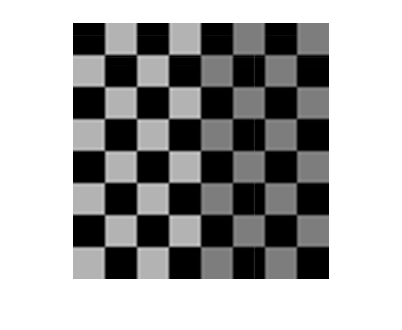

figure(2)
imshow(L)

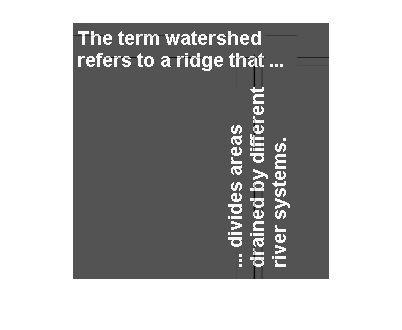

figure(3)
imshow(S,[])

function y = softthresholding(x,lambda)
    y = sign(x).*max(abs(x)-lambda,0);
end

function y = proxnuclearnorm(x,lambda)
    [U,S,V] = svd(x,'econ');
    T = softthresholding(S,lambda);
    S(1:size(T,1),1:size(T,2)) = T;
    y = U*S*V';
end

© Copyright, Shogo MURAMATSU, All rights reserved.